Aquí se hace el método del gradiente ascendente para 3 dimensiones. 

clear
close all
hold off

%HACER ANIMACIÓN DE TODO ESTO

%Vamos a representar cómo se mueve el centro de la formación

N=6; %Número de robots (a partir de N=6 buena aproximación)
iteration=500; %Número de iteraciones
step_size=0.1;
D=1; %Radio de la formación
S=10^-4*[100,1,1;1,1,0;1,0,10]; %Matriz
c0=[20;20;20]; %Posición del centro inicial (initial guess)
r0=[0 0 0]'; %Centro de contaminación
w0=1; %Movimiento circular de un radián por segundo

colors=["ob","ok","or","oy","og","om","oc","ob"];
tf=20;
t=linspace(0,tf,iteration);

%Condiciones iniciales
c(:,1)=c0;
r_c(:,1)=c(:,1)-r0;
mod_r_c(1)=norm(r_c(:,1));
pos_rob=zeros(3,N,iteration);

%Se aplica el método del gradiente
for i=2:iteration
        grad_sum=0;
        for j=1:N
            %Determinación del ángulo azimutal
            phi=w0*t(i)+2*pi*j/N;
            %Determinación del ángulo polar
            if rem(j,2)==0
                theta=pi-0.955316618;
            else
                theta=0.955316618;
            end
            %Posición del robot individual (esfera)
            r_i=c0+D*[sin(theta)*cos(phi);sin(theta)*sin(phi);cos(theta)];
            pos_rob(:,j,i)=r_i;
            %Suma para el gradiente (se tiene en cuenta cada
            %robot)
            grad_sum=grad_sum+100*exp(-r_i'*S*r_i)*(r_i-c0);
        end
    %Aproximación del gradiente en el centro
    grad_centr=3/(N*D^2)*grad_sum;
    grad_exacto=calcular_gradiente3D(c0);
    error_gradiente(i)=norm(grad_centr-grad_exacto);
    L(i)=error_gradiente(i)/(3*D);
    %Aplicación del método del gradiente ascendente
    c(:,i)=c0+step_size*grad_centr;
    c0=c(:,i);
    %Sacar el módulo de la diferencia entre el centro y el punto de
    %contaminación para cada iteración
    mod_r_c(i)=norm(c0-r0); 
end

Representación del centro:

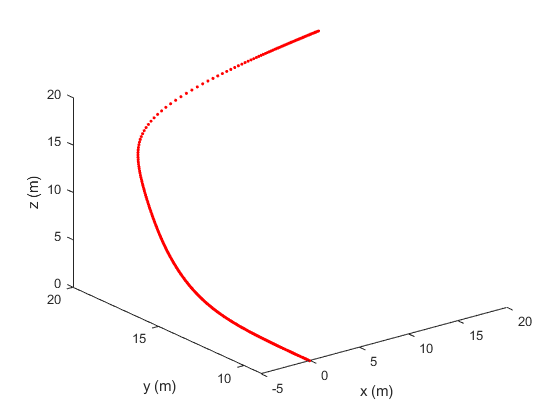

plot3(c(1,:),c(2,:),c(3,:),'.r')
xlabel('x (m)')
ylabel('y (m)')
zlabel('z (m)')

Representación de los robots:

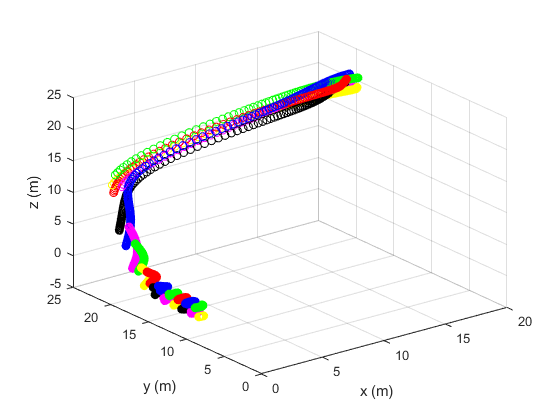

for g=1:N
    for z=2:iteration
        plot3(pos_rob(1,g,z),pos_rob(2,g,z),pos_rob(3,g,z),colors(g))
        hold on
    end
end
xlabel('x (m)')
ylabel('y (m)')
zlabel('z (m)')
axis([0 20 0 25 -5 25])
grid on
hold off

Módulo de la diferencia:

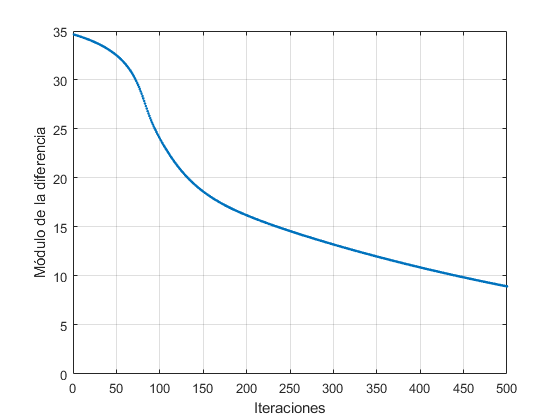

plot(1:iteration,mod_r_c,".")
xlabel("Iteraciones")
ylabel("Módulo de la diferencia")
axis([0 500 0 35])
grid on

%error final para cada step-size
error_final=norm(c(:,iteration)-r0)

error_final = 8.9411

centro_final=c0

centro_final =    -0.0905
    8.9406
    0.0158


L_max=max(L)

L_max = 0.0091